F = readNPY('/Users/platel/Desktop/exp/erwan/M2/combined/F.npy');
iscell=readNPY('/Users/platel/Desktop/exp/erwan/M2/combined/iscell.npy');

%%use of rastermap on winactive part of recording
 
ops.nC = 20;%, number of clusters to use 
ops.iPC = 1:20;%, number of PCs to use 
ops.isort = [];%, initial sorting, otherwise will be the top PC sort
ops.useGPU = 0;%, whether to use the GPU
ops.upsamp = 100;%, upsampling factor for the embedding position
ops.sigUp = 1;%, % standard deviation for upsampling

%preprocessing signal
%DF=Tr1b./std(Tr1b,0,2);

DF=double(F(iscell(:,1)>0,:));
DF=double(F);
NCell=size(DF,1);
Nz=size(DF,2);

ws = warning('off','all');
for i=1:NCell
    p0=polyfit(1:Nz,DF(i,:),3);
    DF(i,:)=DF(i,:)./polyval(p0,1:Nz);
end
warning(ws)%% preprocessing
DF = sgolayfilt(DF',3,7)';%was at 5
DF=normalize(DF,2,"center");
Tr1b=DF(iscell(:,1)>0,:);

% [isort1, isort2, Sm] = mapTmap(DF(:,WinActive),ops);
[isort1, isort2, Sm] = mapTmap(Tr1b,ops);

Elapsed time is 2.698607 seconds.
Elapsed time is 3.563789 seconds.


temps=linspace(0,Nz*1/10.2,Nz);

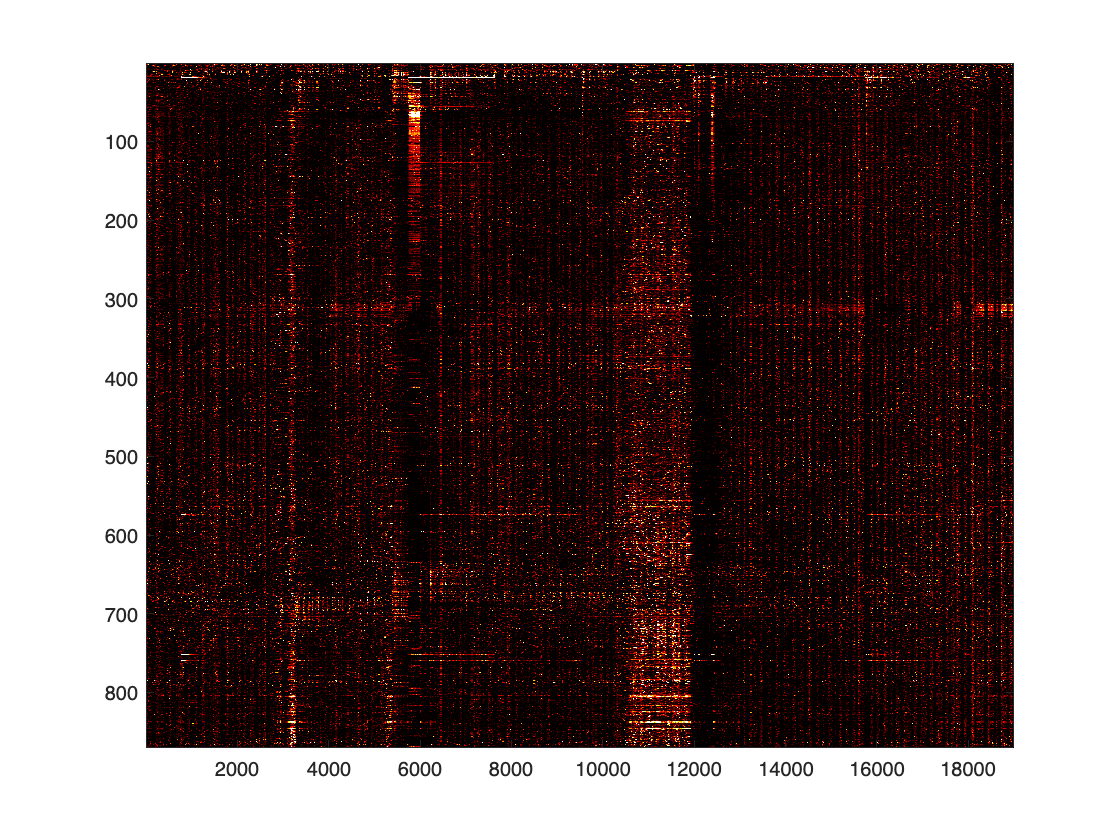

figure
Ftemp=smoothdata(Tr1b,2,"gaussian",20);
 Ftemp=smoothdata(Ftemp,1,"gaussian",3);
imagesc(Ftemp(isort1,:))
% imagesc(Race)
colormap ("hot")
caxis ([0 0.6])

% plot (-speed*10)
% plot (-binary_signal*20)

figure
plot(temps,DF(2,:),Color='k')

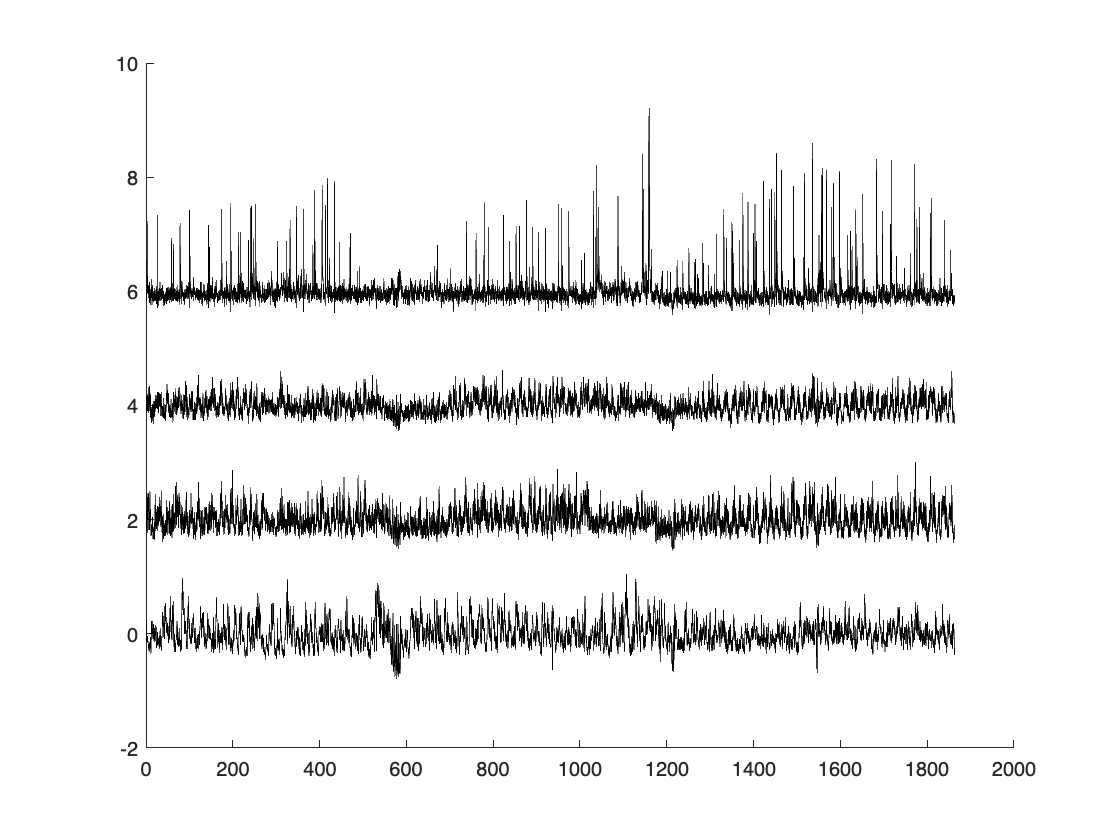

hold on
plot(temps,DF(693,:)+2,Color='k')
plot(temps,DF(850,:)+4,Color='k')
plot(temps,DF(122,:)+6,Color='k')
hold off
box off

% hold off

% ylim([-350 NCell]) 

figure
deb=1

deb = 1

hold on
for n=deb:deb+30

    % plot (-speed*10)
    % plot (-binary_signal*20)
    plot(DF(n,:)+n)

end
hold off

sce_trace=zeros(1,19000);
sce_trace_calc=zeros(1,19000);
sce_trace(TRace)=2;
sce_trace_calc(TRace)=1;

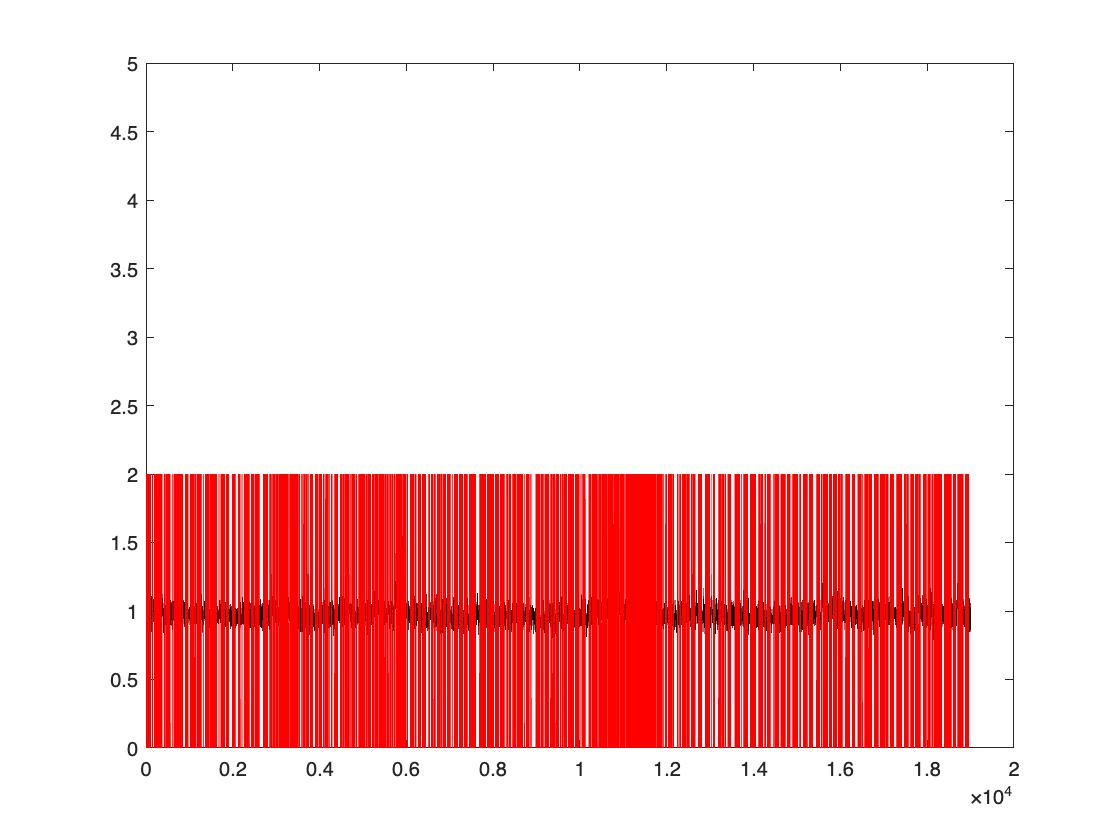

figure
plot(Tr1b(27,:),Color='k')
hold on
plot(sce_trace,Color='red')
ylim([0 5]) 

% [amplitude,locs] = findpeaks(Tr1b(2,:),'MinPeakProminence',0.2);
locs=find (Tr1b(2,:)>1)

locs =      1     2     3     4     5     6     7     8     9   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148   149   150   151   152   153   154   155   156   157   158   159   174   175   176   177   178   179   180   181   182


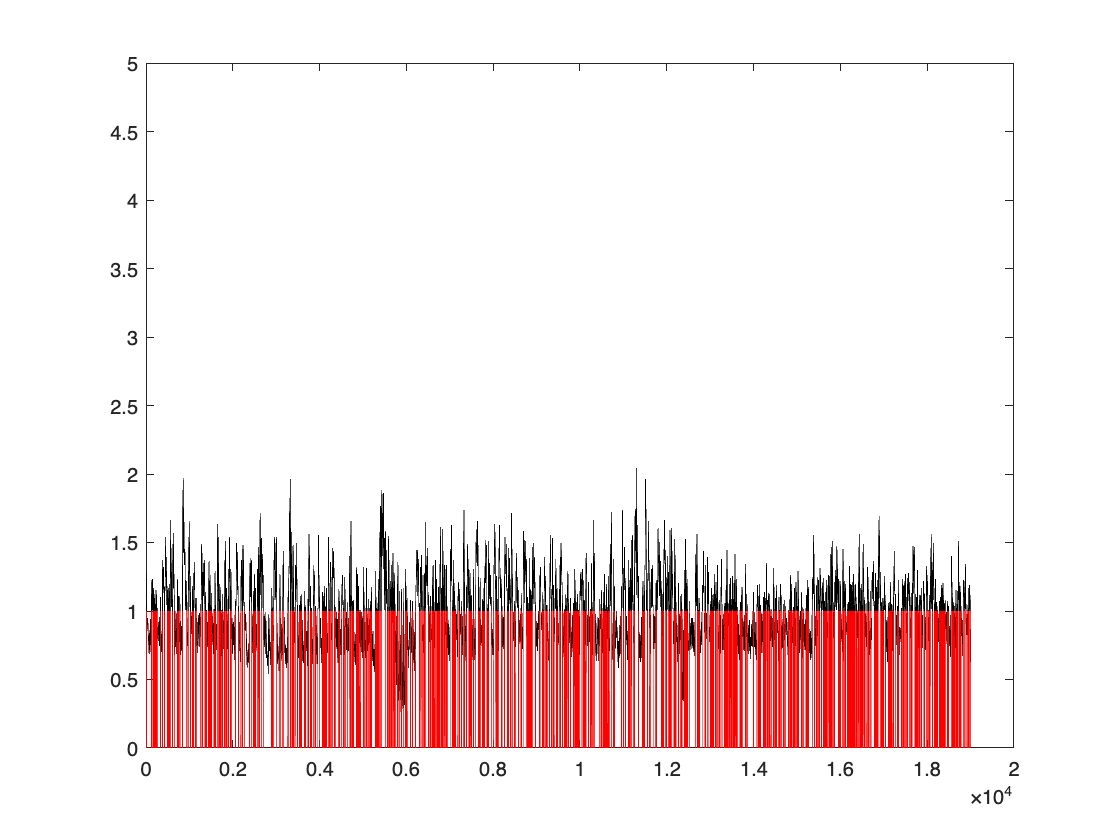

locs_peak=zeros(1,19000);
locs_peak(locs)=1;
figure
plot(Tr1b(2,:),Color='k')
hold on
plot(locs_peak,Color='red')
ylim([0 5]) 

maxlag=100;

[cross_corr, lags] = xcorr(locs_peak, sce_trace_calc,maxlag,"coeff");
[max_corr, idx_max_corr] = max(cross_corr);
lag_at_max_corr = lags(idx_max_corr);
max_corr_values= max_corr

max_corr_values = 0.1992

lags_at_max_corr = lag_at_max_corr

lags_at_max_corr = -68

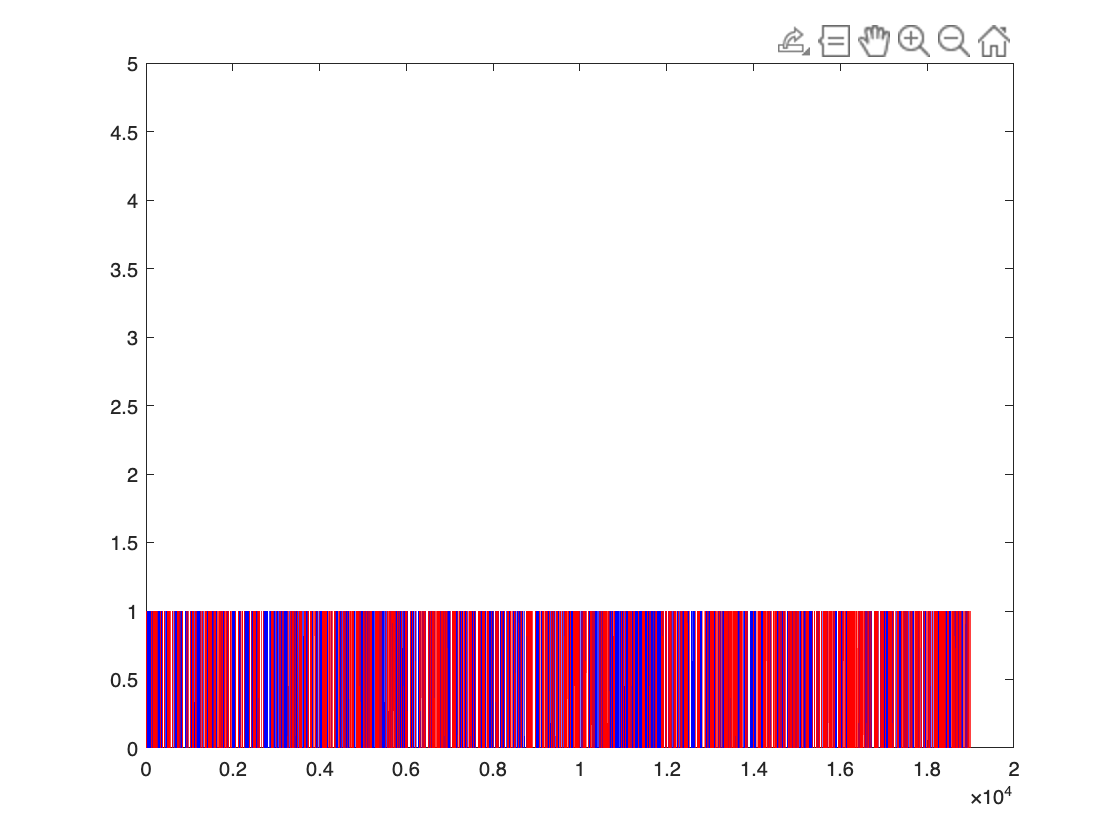

figure
plot(sce_trace_calc,Color='blue')
hold on
plot(locs_peak,Color='red')
ylim([0 5]) 

%find intersection interneuron SCE 
list=[1 2 3 4 5 6 7 8 9 10 15 16 19 21 22 25 26 27 30]%

list =      1     2     3     4     5     6     7     8     9    10    15    16    19    21    22    25    26    27    30


for n=list
    locs=find (Tr1b(n,:)>1);
    intersection_SCE_interneuron=intersect(locs, TRace);
    test=numel(intersection_SCE_interneuron)/numel(TRace)*100;
    disp (['%SCE during interneuron activity: ' num2str(test) ' %'])
end

%SCE during interneuron activity: 48.8424 %
%SCE during interneuron activity: 35.6236 %
%SCE during interneuron activity: 52.5765 %
%SCE during interneuron activity: 52.4272 %
%SCE during interneuron activity: 56.6094 %
%SCE during interneuron activity: 54.2942 %
%SCE during interneuron activity: 52.2778 %
%SCE during interneuron activity: 53.3981 %
%SCE during interneuron activity: 47.7222 %
%SCE during interneuron activity: 43.764 %
%SCE during interneuron activity: 52.8006 %
%SCE during interneuron activity: 45.183 %
%SCE during interneuron activity: 55.4145 %
%SCE during interneuron activity: 47.05 %
%SCE during interneuron activity: 52.3525 %
%SCE during interneuron activity: 57.3562 %
%SCE during interneuron activity: 56.3854 %
%SCE during interneuron activity: 57.2816 %
%SCE during interneuron activity: 30.1718 %
